# Lab4 The Continuous-Time Fourier Transform

应逸雯12210159 陈薇羽12210460

通过本实验的练习，掌握了以下技能：

1.利用fft，fftshift计算连续时间信号的傅里叶变换

2.通过改变tau和N来调整连续时间信号的采样频率

3.利用unrap函数使相位变化平缓

4.利用lsim,freqs函数来求解微分方程的频率响应

5.利用residue函数来将频率响应转化为阶跃响应

4.2a 

Find an analytic expression for x(t) = e^(-2|t|) by think of x(t) = g(t) + g(-t), where g(t) = e^(-2t)*u(t). 

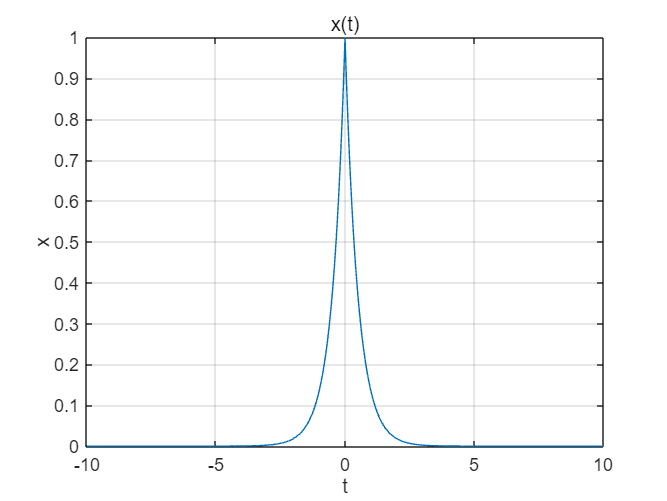

clc,clear,close all;
tau=0.01;T=10;t=[0:tau:T-tau];
tx=[tau-T:tau:T-tau];
g = [zeros(1, length(t)-1), exp(-2*t)];%构造g(t)  
x=g+fliplr(g);%构造x(t)=g(t) + g(-t)
x(length(t))=1;%如果完全按照原题hint构造，x(0)会等于2而非1，所以单独修改x(0)的值
figure;
plot(tx,x);title('x(t)');xlabel('t');ylabel('x');grid on;

4.2b 

Creat the signal  y(t) = x(t - 5)

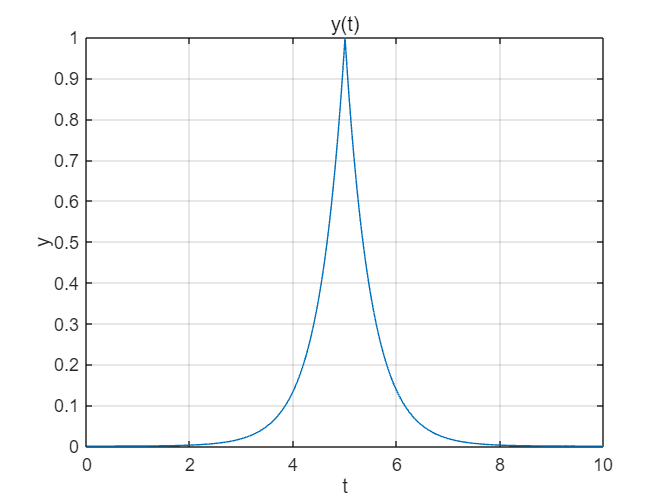

N=T/tau;
y=exp(-2*abs(t-5));%直接构造y(t)
figure;
plot(t,y);title('y(t)');xlabel('t');ylabel('y');grid on;

4.2c Calculate samples Y(jwk) by typing Y=fftshift (tau*fft (y) ). 

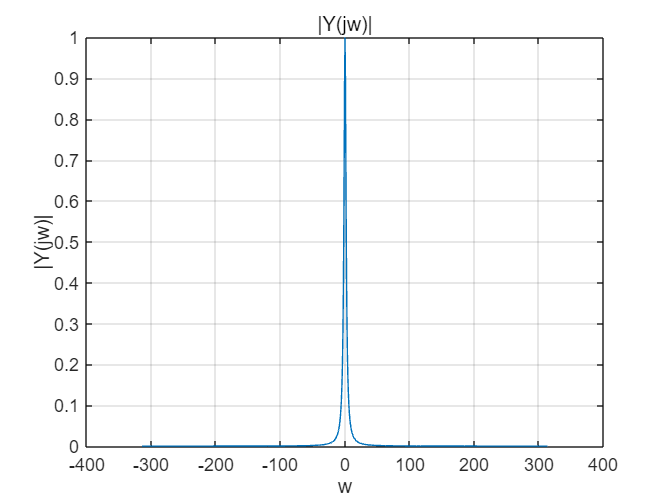

w=-(pi/tau)+(0:N-1)*(2*pi/(N*tau));
Y=fftshift(tau*fft(y));
figure;
plot(w,abs(Y));title('|Y(jw)|');xlabel('w');ylabel('|Y(jw)|');grid on;

4.2d Construct vector w

w=-(pi/tau)+(0:N-1)*(2*pi/(N*tau))

w =  -314.1593 -313.5309 -312.9026 -312.2743 -311.6460 -311.0177 -310.3894 -309.7610 -309.1327 -308.5044 -307.8761 -307.2478 -306.6194 -305.9911 -305.3628 -304.7345 -304.1062 -303.4779 -302.8495 -302.2212 -301.5929 -300.9646 -300.3363 -299.7079 -299.0796 -298.4513 -297.8230 -297.1947 -296.5663 -295.9380 -295.3097 -294.6814 -294.0531 -293.4248 -292.7964 -292.1681 -291.5398 -290.9115 -290.2832 -289.6548 -289.0265 -288.3982 -287.7699 -287.1416 -286.5133 -285.8849 -285.2566 -284.6283 -284.0000 -283.3717


4.2e compute samples of X(jw) directly from Y

分析：y(t)=x(t-5)，所以Y（jw）.*exp(5jw) = X（jw）

X=Y.*exp(5*i*w);

4.2f 分别画出 a 问中的 X(jw)和 e 问中的 X(jw)的幅值和角度图, 利用semilogy 函数比较 a/e 题中 X 的幅值差异

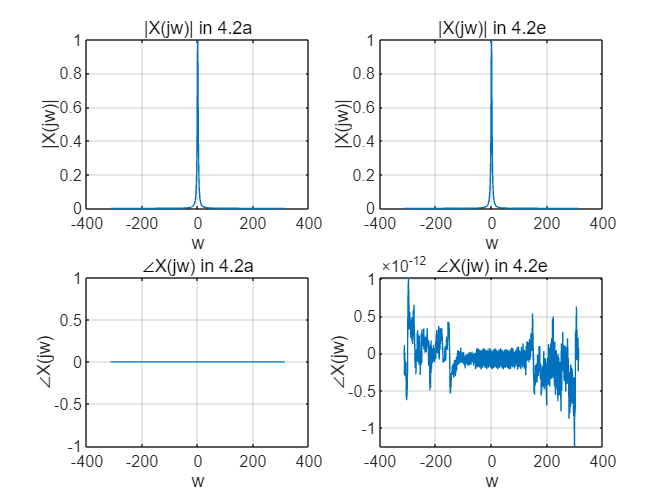

X2= 1 ./ (2 + 1j .* w) + 1 ./ (2 - 1j .* w);
figure;
subplot(2,2,1);
plot(w,abs(X2));title('|X(jw)| in 4.2a');xlabel('w');ylabel('|X(jw)|');grid on;
subplot(2,2,2);
plot(w,abs(X));title('|X(jw)| in 4.2e');xlabel('w');ylabel('|X(jw)|');grid on;
subplot(2,2,3);
plot(w,angle(X2));title('∠X(jw) in 4.2a');xlabel('w');ylabel('∠X(jw)');grid on;
subplot(2,2,4);
plot(w,angle(X));title('∠X(jw) in 4.2e');xlabel('w');ylabel('∠X(jw)');grid on;

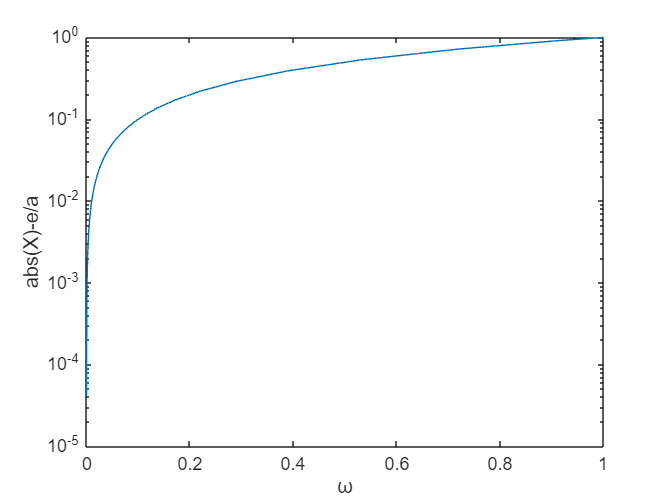

figure
semilogy(abs(X),abs(X2))
ylabel('abs(X)-e/a')
xlabel('ω');

4.2g 画出 Y 的幅值图和相角图，与 X 比较

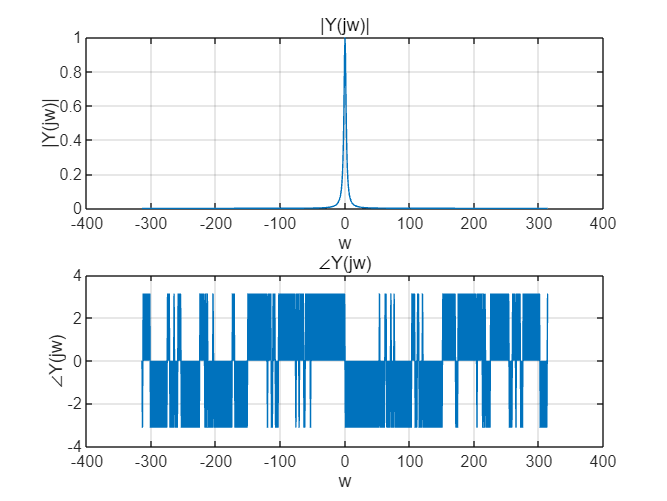

figure;
subplot(2,1,1);
plot(w,abs(Y));title('|Y(jw)|');xlabel('w');ylabel('|Y(jw)|');grid on;
subplot(2,1,2);
plot(w,angle(Y));title('∠Y(jw)');xlabel('w');ylabel('∠Y(jw)');grid on;

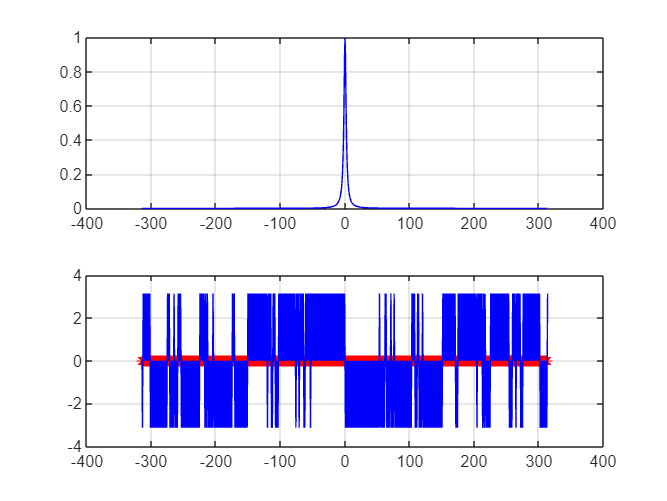

figure;
subplot(2,1,1);
plot(w,abs(Y),'r',w,abs(X),'b');grid on;
subplot(2,1,2);
plot(w,angle(X),'r-*',w,angle(Y),'b');grid on;

如图所示，Y幅值与X一致，相角与X不同。因为Y是X作时移得到的信号，所以幅值不变，相角变化。

4.6 a 加载ctftmod.mat，画出Z的摩斯密码

load ctftmod.mat;
who


您的变量为:

N     T     X     X2    Y     af    bf    dash  dot   f1    f2    g     t     tau   tx    w     x     y     



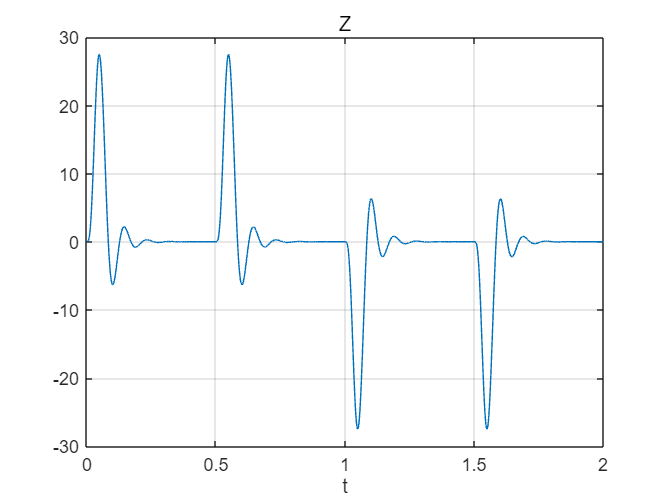

Z=[dash dash dot dot];
figure;
plot(t,Z),xlabel('t'),title('Z'),grid on;

4.6 b 画出频率响应

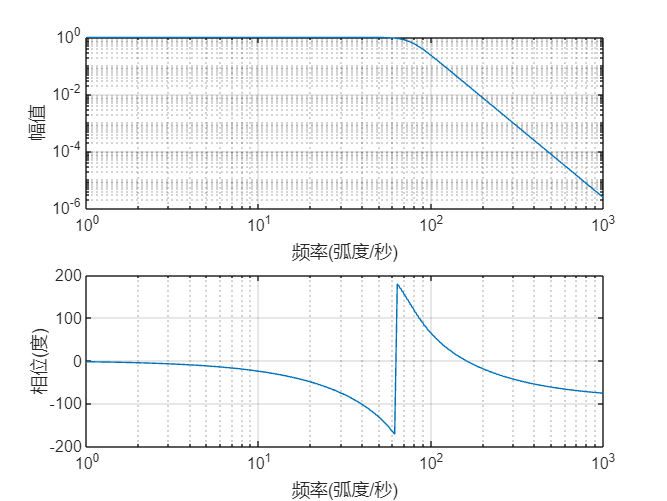

figure;
freqs(bf,af);

4.6 c 对两个信号滤波

分析：根据提示使用lsim，然后画图比较

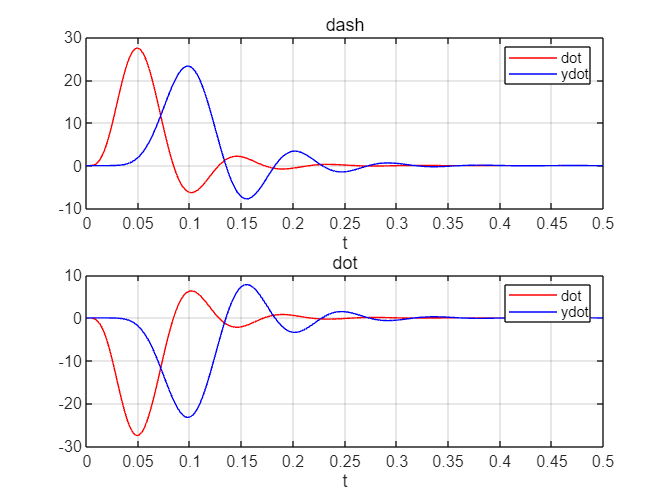

ydash=lsim(bf,af,dash,t(1:length(dash)));
ydot=lsim(bf,af,dot,t(1:length(dot)));
ndash=t(1:length(dash));
ndot=t(1:length(dot));
figure;
subplot(2,1,1),plot(ndash,dash,'r',ndash,ydash,'b'),xlabel('t'),legend('dot','ydot'),title('dash'),grid on;
subplot(2,1,2),plot(ndot,dot,'r',ndot,ydot,'b'),xlabel('t'),legend('dot','ydot'),title('dot'),grid on;

结果如图。

4.6 d 用cos(2pif1t)调制。

先改变信号，然后用lsim

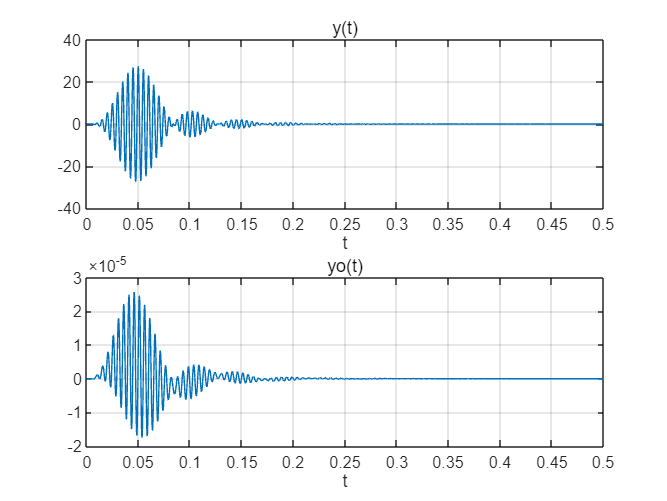

y=dash.*cos(2*pi*f1*t(1:length(dash)));
figure;
subplot(2,1,1),plot(t(1:length(y)),y),xlabel('t'),title('y(t)'),grid on;
yo=lsim(bf,af,y,t(1:length(y)));
subplot(2,1,2),plot(t(1:length(yo)),yo),xlabel('t'),title('yo(t)'),grid on;

波形与原来的ydash类似，但能量大幅损失。

4.6 e 求解傅里叶变换。

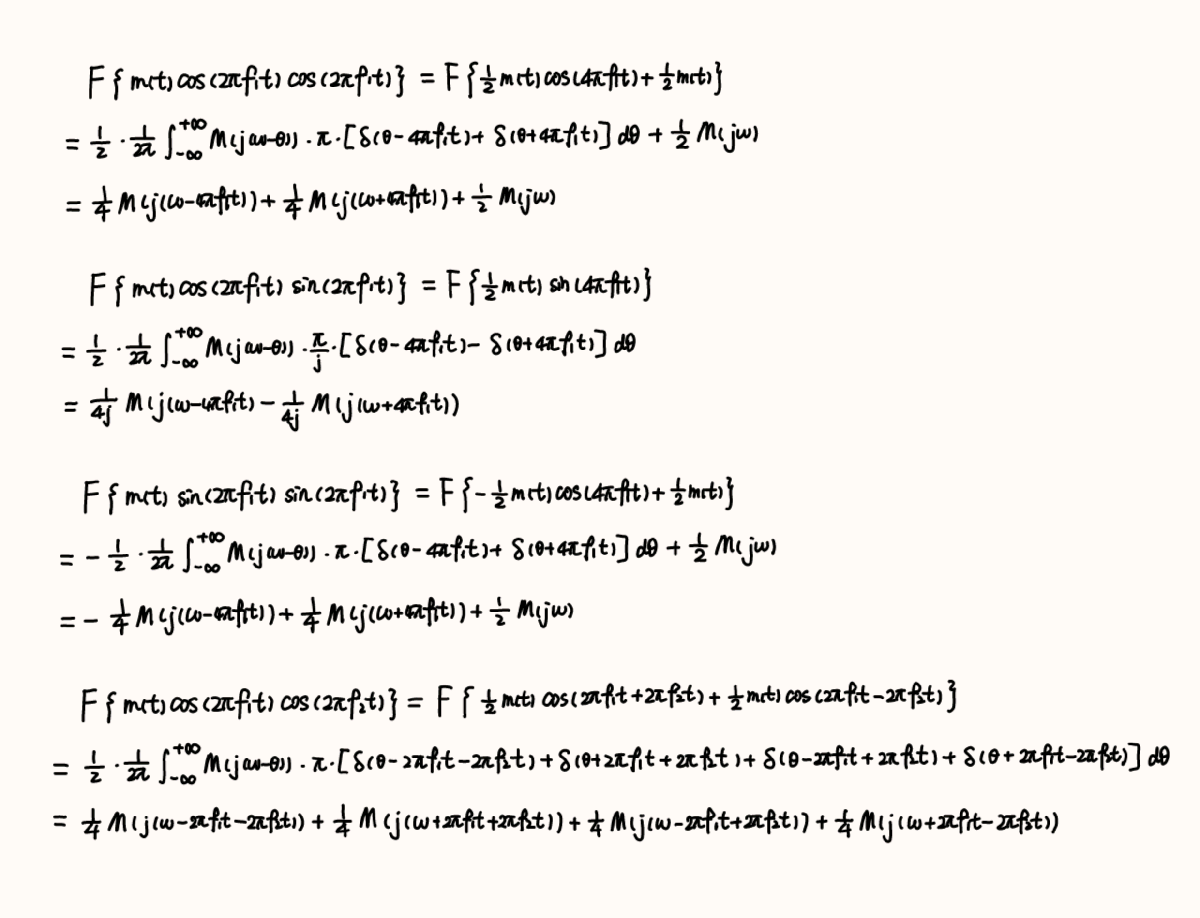

4.6 f 解调信号m1(t)，画出频率响应，判断信号。

x(t)=m1(t)*cos(2*pi*f1*t)+m2(t)*sin(2*pi*f2*t)+m3(t)*sin(2*pi*f1*t)

可以知道m1(t)由cos(2*pi*f1*t)调制。

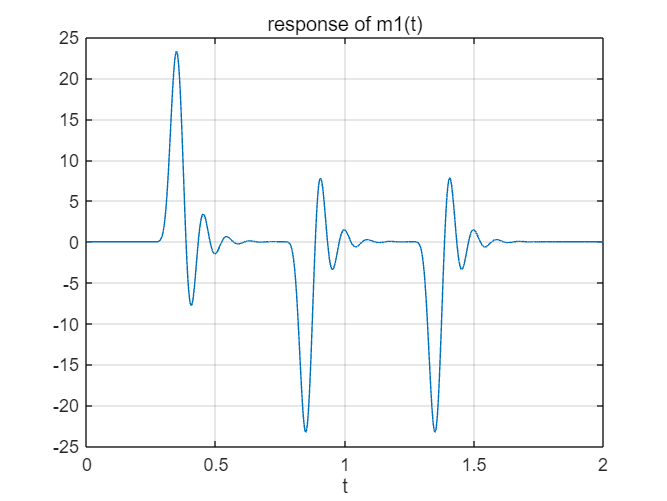

m1=x.*cos(2*pi*f1*t);
m1r=2*lsim(bf,af,m1,t);
figure;
plot(t(1:length(m1r)),m1r),xlabel('t'),title('response of m1(t)'),grid on;

观察图像可以知道，信号是 dash dot dot，对照表格，是D。

4.6 g 解调信号m2(t)，m3(t)，画出频率相应，判断信号。

x(t)=m1(t)*cos(2*pi*f1*t)+m2(t)*sin(2*pi*f2*t)+m3(t)*sin(2*pi*f1*t)

可以知道m2(t)由sin(2*pi*f2*t)调制，m3(t)由sin(2*pi*f1*t)调制。

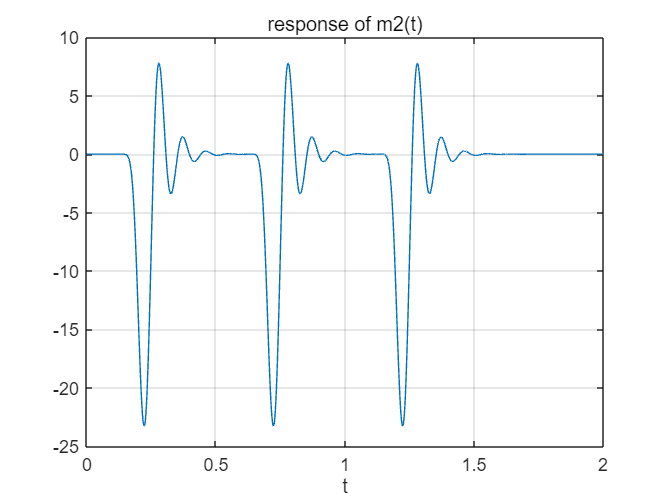

m2=x.*sin(2*pi*f2*t);
m2r=2*lsim(bf,af,m2,t);
figure;
plot(t(1:length(m2r)),m2r),xlabel('t'),title('response of m2(t)'),grid on;

观察图像可以知道，信号是 dot dot dot，对照表格，是S。

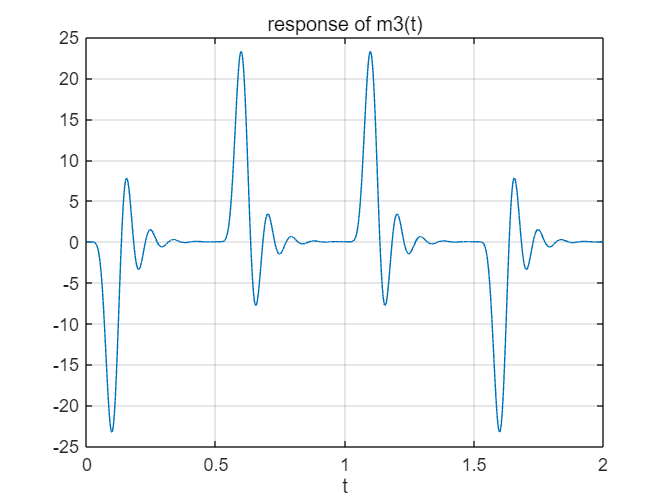

m3=x.*sin(2*pi*f1*t);
m3r=2*lsim(bf,af,m3,t);
figure;
plot(t(1:length(m3r)),m3r),xlabel('t'),title('response of m3(t)'),grid on;

观察图像可以知道，信号是 dot dash dash dot，对照表格，是P。

Agent007的遗言是：The future of technology lies in DSP.

课堂参与证明：

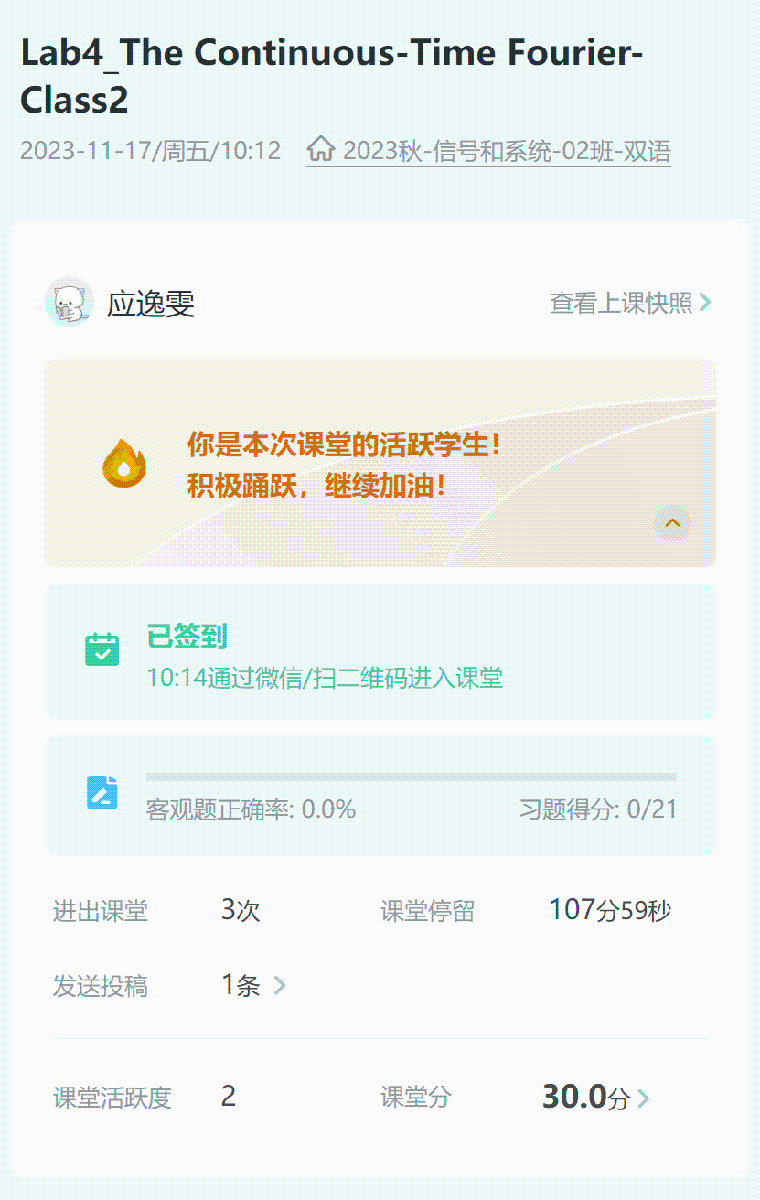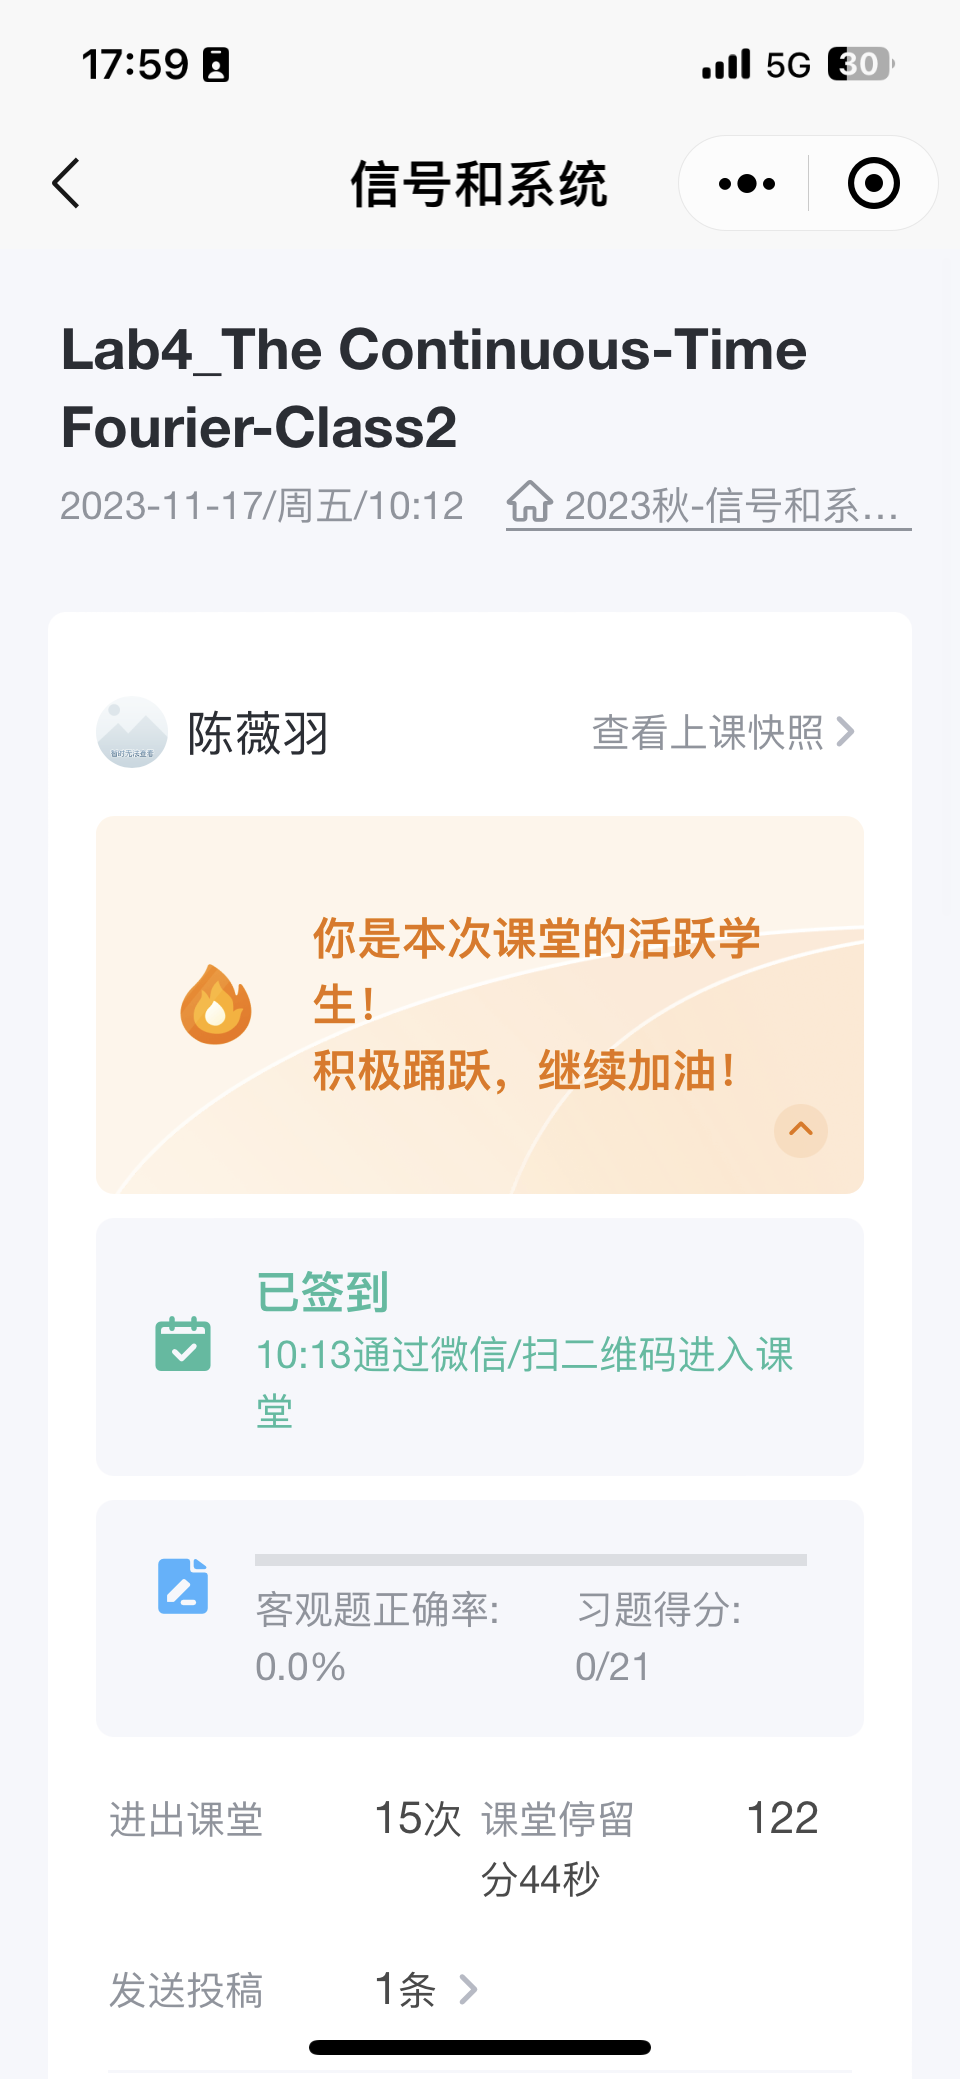

自我评分：

陈薇羽：10/10

应逸雯：10/10